
% Syntax: Arctic_argo_RAW_plot.m
%
% Description
%
% Argo floats within Baltic region. Use Argo as seen in the original
% data base as given by IFREMER-CORIOLIS site
% The results from this script are to contrast the database
% provided by BEC, seen in folder name "SSS>Baltic>BEC>indata")
%
% This version uses the Argo matlab files creted for each basin.
%
% rcatany (2019/10/10)
%
% =========================================================================
clear; clc; close all
re_start = 0; % [1] delete fn_out and start from scratch, or [0] not.

w = warning ('off','all');      % mute warnings
rmpath('folderthatisnotonpath') % check warning are on/off
warning(w)

path_root = '/Volumes/Rogue/';
% path_root = '/Volumes/NOC/data/';

folder_tmp = ['~/Documents/GitHub/tmp/'];
foldercheck_raf(folder_tmp);

folder_out = folder_tmp; % keep folder out as tmp until new order is given

% inputs script
iyear = 2013;
imonth = [1:12];
% iday = 1;

% number of days in the last month of the series
num_days = calendar(iyear(end),imonth(end))';
num_days(num_days == 0) = [];
num_days = length(num_days);

itime_start = datenum(iyear(1),imonth(1),1,0,0,0);
itime_end   = datenum(iyear(end),imonth(end),num_days,0,0,0);

ibasin = 9; % Basin number: 9 (Baltic)
[xmin,xmax,ymin,ymax, basin_str] = map_lim_raf(ibasin);

nyear = length(iyear);

% Plot TS Profiles Limits axes
Tmin = 0;
Tmax = 15;

if ibasin == 7
    Smin = 15;
    Smax = 40;
    
elseif ibasin == 9
    Smin = 0;
    Smax = 10;
    
end

## Read Argo raw files

re_start = 1; % re-start reading Argo raw file from scratch [1], or not [0]
A = ar_rd_RAW(ibasin,iyear,imonth,re_start);

Nobs = A.Nobs;

PRES_ADJUSTED_ERROR = A.PRES_ADJUSTED_ERROR;
SALT_ADJUSTED_ERROR = A.SALT_ADJUSTED_ERROR;
TEMP_ADJUSTED_ERROR = A.TEMP_ADJUSTED_ERROR;

temp_qc = A.temp_qc;
salt_qc = A.salt_qc;
pres_qc = A.pres_qc;

lon = A.lon;
lat = A.lat;

time_ar = A.time_ar;
platform = A.platform;

temp = A.temp;
salt = A.salt;
pres = A.pres;

## Interpolate Z-direction (narrow depth levels)

Interpolation specs: Grid dimensions

pres1 = 0;              % min pres bin
pres2 = 300;            % max depth (m) (Baltic depth_max = 300 m)
grid_p = 1;             % interpolant distance (m) between depth levels

int_method = 'linear';              % interpolation method (see doc interp1)
pres_p = [pres1:grid_p:pres2]';     % interpolated presure
zlevels = length(pres_p);           % number of depth levels in the interpolated vars

[i,j] = size(temp);

t2 = nan(zlevels,j);
s2 = nan(zlevels,j);
p2 = ones(zlevels,j).*pres_p;

% interpolate profiles z-axis (depth)
for j = 1 : Nobs
    t1 = temp(:,j);
    s1 = salt(:,j);
    p1 = pres(:,j); % presure levels are the same for all the profiles
    
    ind = isnan(t1) | isnan(p1) | isnan(s1) | p1 > pres2;
    
    p1(ind) = [];
    t1(ind) = [];
    s1(ind) = [];
    
    [p1, index] = unique(p1);
    
    
    dp = diff(p1);
    
    if min(dp) >= 0.01
        t2_interp = interp1(p1,t1(index),pres_p,int_method);
        t2(:,j) = t2_interp;
        
        s2_interp = interp1(p1,s1(index),pres_p,int_method);
        s2 (:,j) = s2_interp;
    end
    % clear vars within loop
    clear t1 s1 p1 ind
end

t_intp = t2;
s_intp = s2;
p_intp = p2;

## Argo Temperature and Salinity values

T_ar = t_intp;
S_ar = s_intp;
P_ar = p_intp;

clear t2 s2 p2
% 1/ plot T and S Argo profiles, raw Vs interp

nprof = find(platform==3901940); % Location North Atlantic [20161101]
% nprof = find(platform == 4901821); % Location: East Pacific [20161101];

if ~isempty(nprof)
    
    T = temp (:,nprof);
    S = salt (:,nprof);
    P = pres (:,nprof);
    
    T_intp = t_intp(:,nprof);
    S_intp = s_intp(:,nprof);
    P_intp = p_intp(:,nprof);
    
    plat = platform(nprof);
    
    Tmin = 0;
    Tmax = 15;
    Smin = 15;
    Smax = 40;
    
    figure(2); clf
    
    % [1] Temperature profile
    subplot(1,2,1)
    h1 = plot (T, -P,'ko','markersize',10);
    hold on
    h2 = plot (T_intp, -P_intp,'ko','MarkerFaceColor','r');
    
    ylim([-pres2 -pres1])
    xlim ([Tmin Tmax])
    
    xlabel ('T (\circ)'); ylabel('depth (m)')
    grid on
    legend ([h1(1);h2(1)],{'raw';'interp'},'location','SouthWest')
    title(['plaform: ' num2str(plat(1))]);
    
    % [2] Salinity profile
    subplot(1,2,2)
    h1 = plot (S, -P,'ko','markersize',10);
    hold on
    h2 = plot (S_intp(:,1), -P_intp,'ko','MarkerFaceColor','b');
    
    ylim([-pres2 -pres1])
    xlim ([Smin Smax])
    
    xlabel ('S (psu)'); ylabel('depth (m)')
    grid on
    legend ([h1(1);h2(1)],{'raw'  ;'interp'},'location','SouthWest')
    title(['plaform: ' num2str(plat(1))]);
end

## Argo profile Classification

This sections makes two types of Argo classification, which are: Regional classification (Sub) regional Classification

- Bothian Sea [*] (BOS) [61.5?N,19?E]

- Gulf of Finland (GOF) 

- Northern Baltic Proper (NBP)

- Arkona Basin [*] (ArB) [55?N, 16?E]

[*] data to be presented in this validation. These regions contain both Argo and mooring data (i.e. allow study of MLD Argo Vs Mooring). Seasonal Classification

- Winter (wnt): December, January, February

- Spring (spr): March, April, May

- Summer (sum): June, July, August

- Autumn (aut): September, October, November

% Select Argo Floats within a searching distance 'r' (km) from region
% centre
r = 100; % radius (km)

lon_BOS = 19.5;
lat_BOS = 61.5;

lon_GOF = 21.5;
lat_GOF = 59.5;

lon_NBP = 19.5;
lat_NBP = 58.50;

lon_ArB = 18;
lat_ArB = 56;



### Plot Study region locations

 

% Set the map projection specifications
map_projection = 'merc';
lon_min = xmin;
lon_max = xmax;
lat_min = ymin;
lat_max = ymax;

lon_step = 10;
lat_step = 5;

figure; hold on

fillmap_super(map_projection,...
    lon_min,lon_max,lat_min,lat_max,lon_step,lat_step);
hold on

% h0 = plotm(lat,lon,'kp','MarkerFaceColor','r','MarkerSize',5);

h1 = plotm(lat_BOS,lon_BOS,...
    'kp','MarkerFaceColor','g','MarkerSize',10); hold on
[c1] = plotm_study_region(lon_BOS,lat_BOS,r);

ans =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


set(c1,'color','k','linewidth',2)

h2 = plotm(lat_GOF,lon_GOF,...
    'kp','MarkerFaceColor','g','MarkerSize',10); hold on
[c1] = plotm_study_region(lon_GOF,lat_GOF,r);

ans =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


set(c1,'color','k','linewidth',2)

h2 = plotm(lat_NBP,lon_NBP,...
    'kp','MarkerFaceColor','g','MarkerSize',10); hold on
[c1] = plotm_study_region(lon_NBP,lat_NBP,r);

ans =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


set(c1,'color','k','linewidth',2)

h2 = plotm(lat_ArB,lon_ArB,...
    'kp','MarkerFaceColor','g','MarkerSize',10); hold on
[c1] = plotm_study_region(lon_ArB,lat_ArB,r);

ans =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


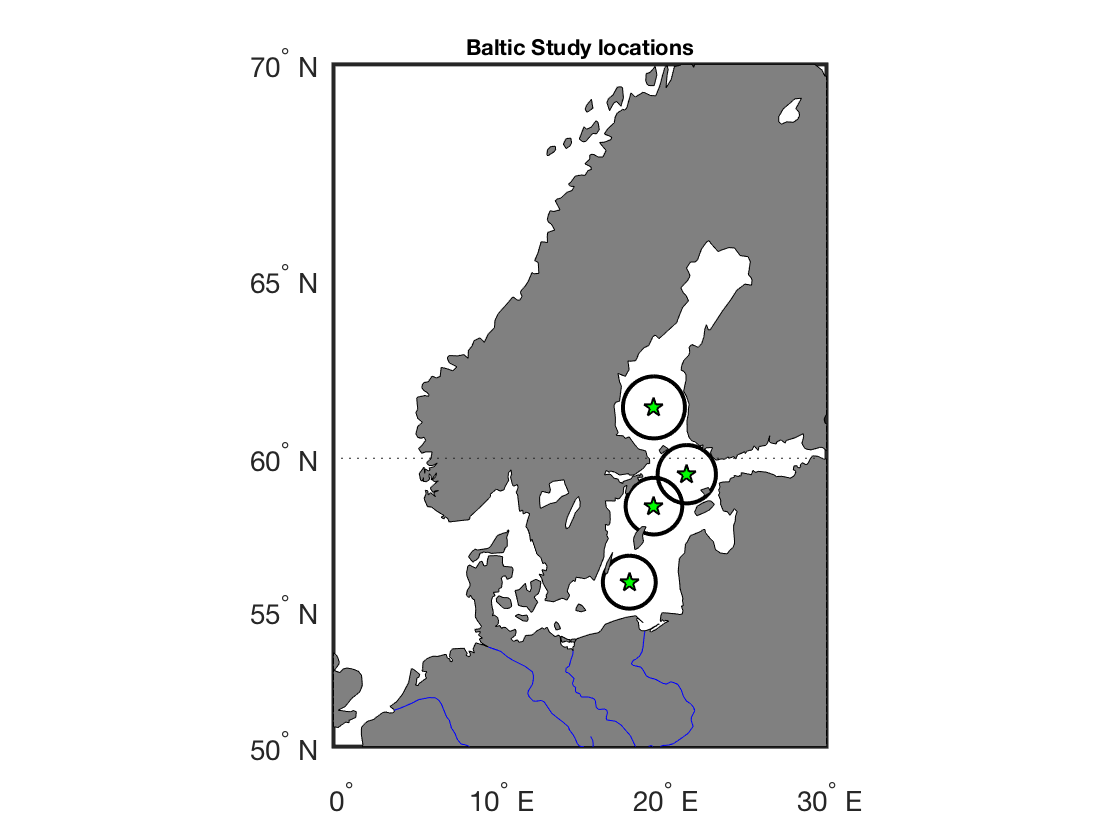

set(c1,'color','k','linewidth',2)



% legend([h1(1),h2(1)],{'BOS''ArB'},'location','SouthEast');

framem on
axis off
tightmap
geoshow('landareas.shp','facecolor',[1 1 1].*0.5)
rivers = shaperead('worldrivers', 'UseGeoCoords', true);
geoshow(rivers, 'Color', 'blue')
gridm on
title({[basin_str ' Study locations']})

## Regional Argo Selection Bothian Sea

DIST_BOS = Distance(lon_BOS,lat_BOS,lon,lat);
DIST_ArC = Distance(lon_ArB,lat_ArB,lon,lat);

ind_ar_BOS = find(DIST_BOS <= r);
ind_ar_ArB = find(DIST_ArC <= r);


lon_ar_BOS = lon(ind_ar_BOS);
lat_ar_BOS = lat(ind_ar_BOS);

plat_BOS = platform(ind_ar_BOS);

S_ar_BOS = S_ar(:,ind_ar_BOS);
T_ar_BOS = T_ar(:,ind_ar_BOS);
P_ar_BOS = P_ar(:,ind_ar_BOS);

lon_ar_ArB = lon(ind_ar_ArB);
lat_ar_ArB = lat(ind_ar_ArB);

plat_ArB = platform(ind_ar_ArB);

S_ar_ArB = S_ar(:,ind_ar_ArB);
T_ar_ArB = T_ar(:,ind_ar_ArB);
P_ar_ArB = P_ar(:,ind_ar_ArB);


% [+] ARGO seasonal classificaton index of year
time_ar_season = datevec(time_ar);

ind_ar_wnt = ismember(time_ar_season(:,2), [12,1,2]); % winter months (wnt)
ind_ar_spr = ismember(time_ar_season(:,2), [3,4,5]);  % spring months (spr)
ind_ar_sum = ismember(time_ar_season(:,2), [6,7,8]);  % summer months (sum)
ind_ar_aut = ismember(time_ar_season(:,2), [9,10,11]);% autumn months (aut)

% [+] Argo number of profiles each season
Nobs_ar_BOS = length(ind_ar_BOS);
Nobs_ar_ArB = length(ind_ar_ArB);

Nobs_ar_wnt = sum(ind_ar_wnt);
Nobs_ar_spr = sum(ind_ar_spr);
Nobs_ar_sum = sum(ind_ar_sum);
Nobs_ar_aut = sum(ind_ar_aut);


lat_wnt = lat(ind_ar_wnt);
lon_wnt = lon(ind_ar_wnt);
lat_spr = lat(ind_ar_spr);
lon_spr = lon(ind_ar_spr);
lat_sum = lat(ind_ar_sum);
lon_sum = lon(ind_ar_sum);
lat_aut = lat(ind_ar_aut);
lon_aut = lon(ind_ar_aut);

### Plot Geolocation: ARGO floats within Baltic region 

#### 1) ALL Argo floats

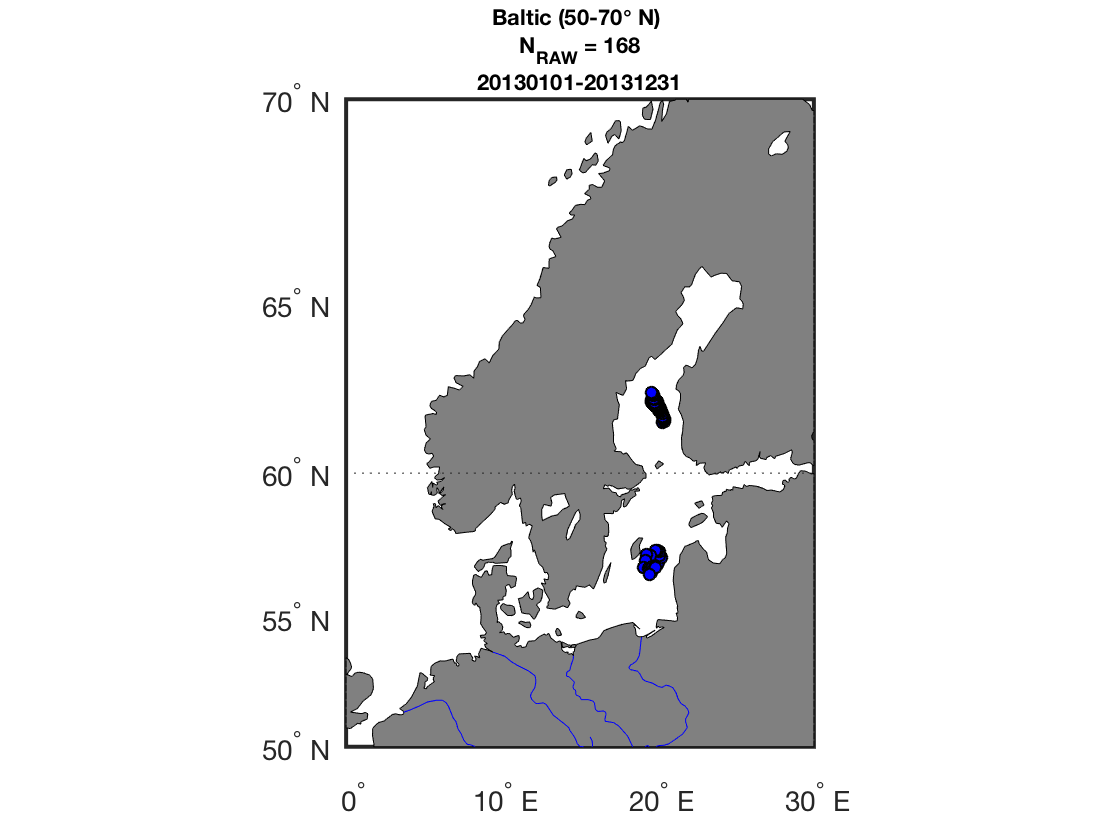

% Set the map projection specifications
 
map_projection = 'merc';
lon_min = xmin;
lon_max = xmax;
lat_min = ymin;
lat_max = ymax;

lon_step = 10;
lat_step = 5;

%figure; hold on
fillmap_super(map_projection,...
    lon_min,lon_max,lat_min,lat_max,lon_step,lat_step);
hold on

title({[basin_str ' (' num2str(lat_min) '-' ...
    num2str(lat_max) '\circ N) ' ]; ...
    ['N_{RAW} = ' num2str(Nobs)];...
    [datestr(itime_start,'yyyymmdd') '-'...
    datestr(itime_end,'yyyymmdd')]});


h1 = plotm(lat,lon,'ko','MarkerFaceColor','r');
h2 = plotm(lat,lon,'ko','MarkerFaceColor','b');


% legend([h1(1),h2(1)],{['Nobs_{NA}=' num2str(Nobs_NA)],...
%     ['Nobs_{PA}=' num2str(Nobs_PA)]},'location','southeastoutside')

#### 2) Argo floats in Winter

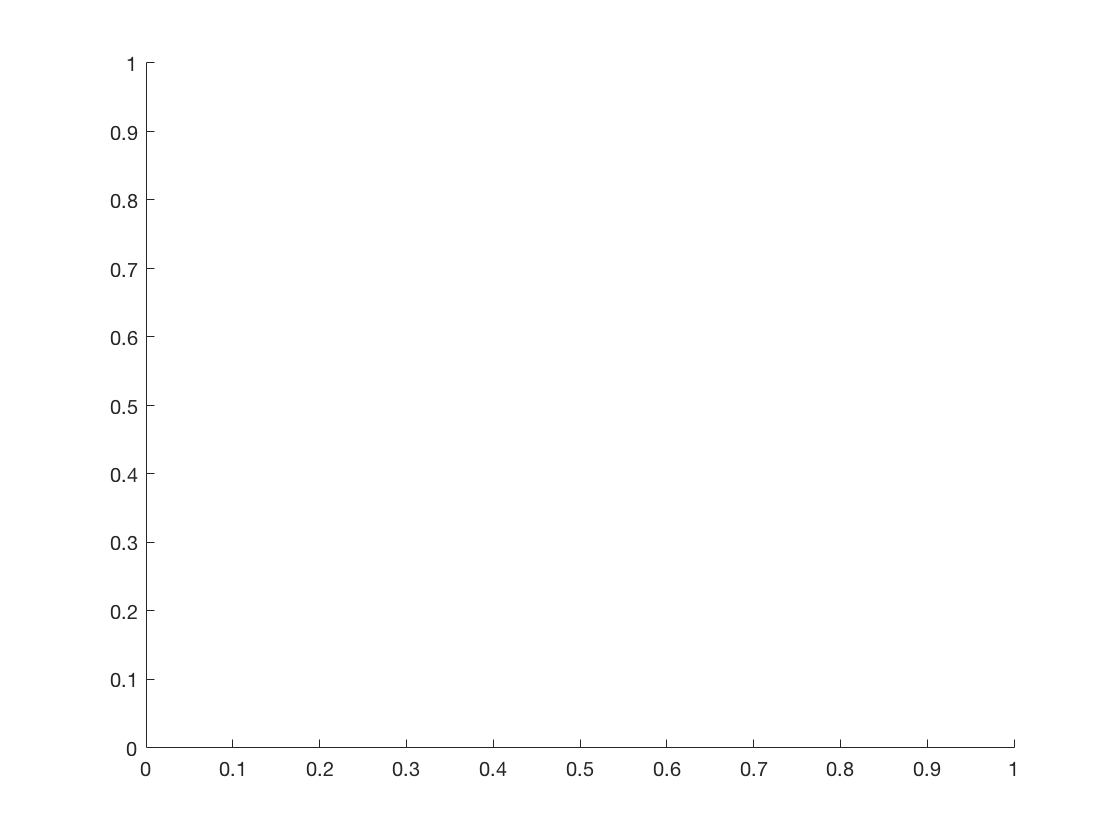

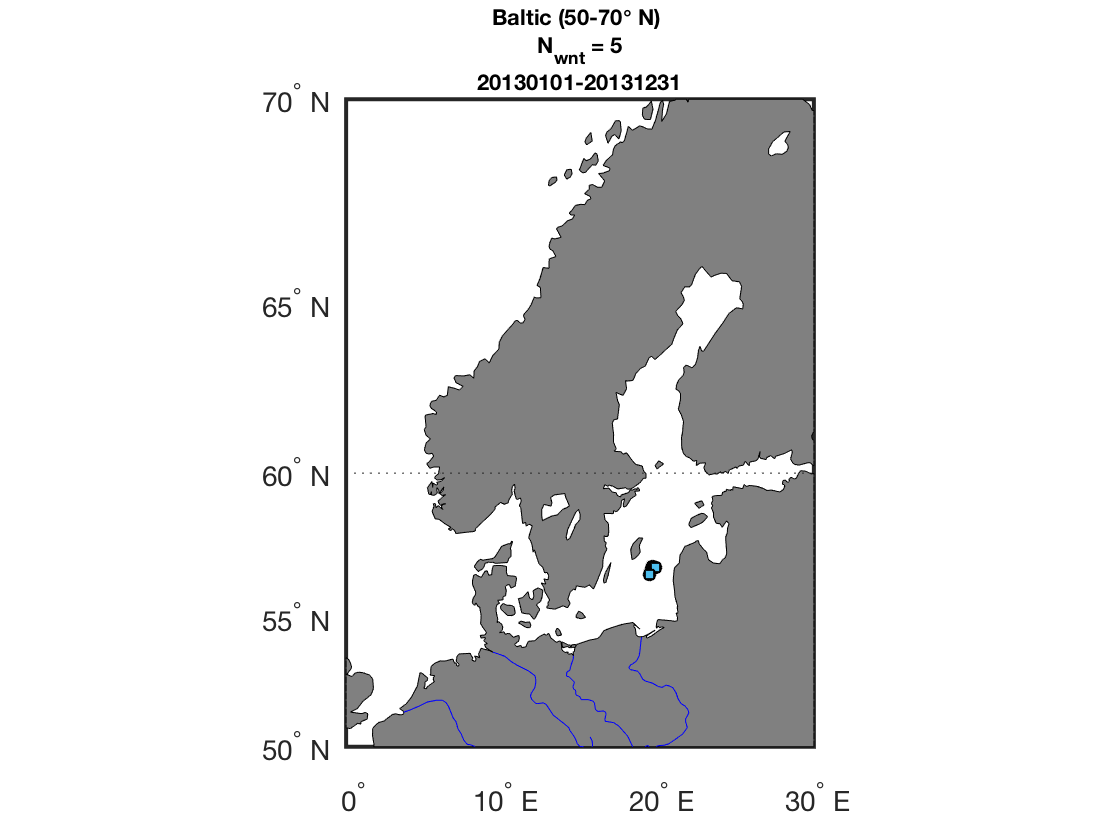

if sum(ind_ar_wnt)~=0 || sum(ind_ar_wnt)~=0
    
    figure; clf; hold on
    
    map_projection = 'merc';
    lon_min = xmin;
    lon_max = xmax;
    lat_min = ymin;
    lat_max = ymax;
    
    lon_step = 10;
    lat_step = 5;
    
    figure; hold on
    fillmap_super(map_projection,...
        lon_min,lon_max,lat_min,lat_max,lon_step,lat_step);
    hold on
    
    title({[basin_str ' (' num2str(lat_min) '-' ...
        num2str(lat_max) '\circ N) ' ]; ...
        ['N_{wnt} = ' num2str(Nobs_ar_wnt)];...
        [datestr(itime_start,'yyyymmdd') '-'...
        datestr(itime_end,'yyyymmdd')]});
    hold on
    
    h1 = plotm(lat_wnt,lon_wnt,...
        'ko','MarkerFaceColor',[0.3020    0.7451    0.9333]);
    h2 = plotm(lat_wnt,lon_wnt,...
        'ks','MarkerFaceColor',[0.3020    0.7451    0.9333]);
    
    %     legend([h1(1),h2(1)],{['Nobs_{wnt}=' num2str(Nobs_ar_wnt)],...
    %         ['Nobs_{PA}=' num2str(Nobs_ar_PA_wnt)]},'location','southeastoutside')
    
end

#### 3) Argo floats in Spring

if sum(ind_ar_spr)~=0 || sum(ind_ar_spr)~=0
    figure; clf; hold on
    
    map_projection = 'merc';
    lon_min = xmin;
    lon_max = xmax;
    lat_min = ymin;
    lat_max = ymax;
    
    lon_step = 10;
    lat_step = 5;
    
    figure; hold on
    fillmap_super(map_projection,...
        lon_min,lon_max,lat_min,lat_max,lon_step,lat_step);
    hold on
    
    title({[basin_str ' (' num2str(lat_min) '-' ...
        num2str(lat_max) '\circ N) ' ]; ...
        ['N_{spr} = ' num2str(Nobs_ar_spr)];...
        [datestr(itime_start,'yyyymmdd') '-'...
        datestr(itime_end,'yyyymmdd')]});
    hold on
    
    icolor = [1     1     0]; % set FaceColor (c = uisetcolor)
    h1 = plotm(lat_spr,lon_spr,'ko','MarkerFaceColor',icolor);
    h2 = plotm(lat_spr,lon_spr,'ks','MarkerFaceColor',icolor);
    
    %     legend([h1(1),h2(1)],{['Nobs_{NA}=' num2str(Nobs_ar_NA_spr)],...
    %         ['Nobs_{PA}=' num2str(Nobs_ar_PA_spr)]},'location','southeastoutside')
    
end

#### 4) Argo floats in Summer

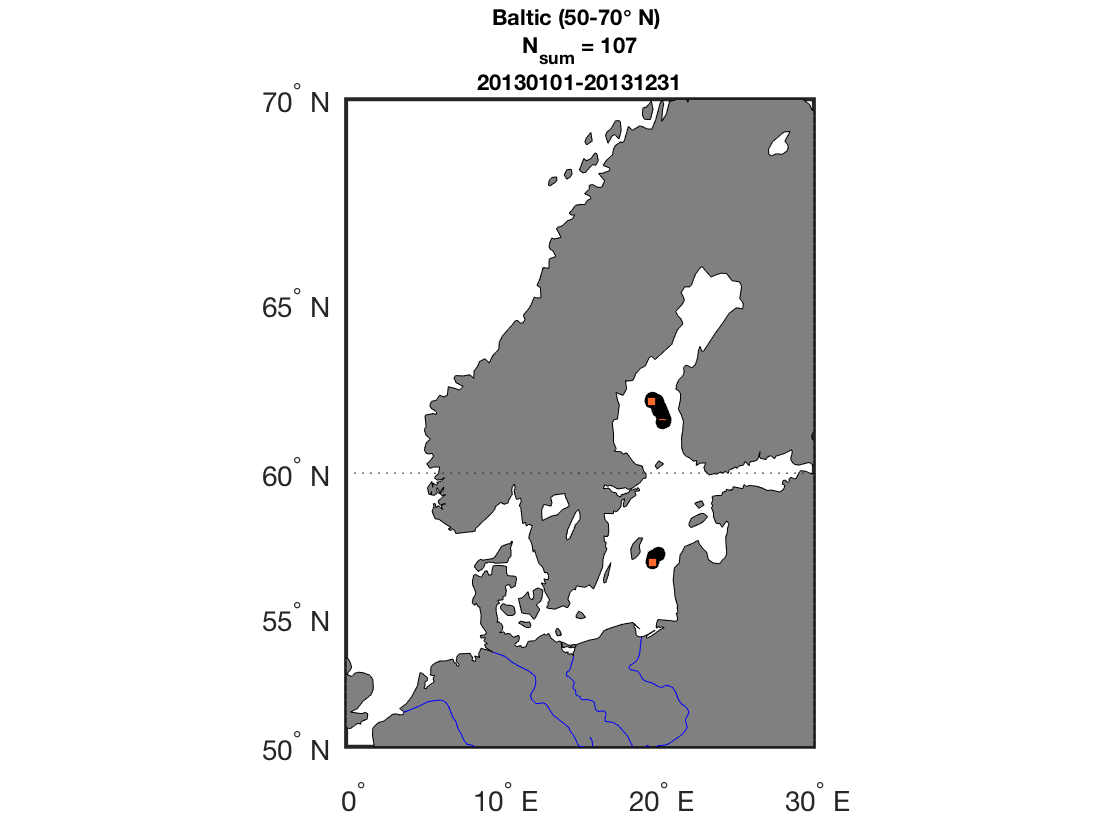

if sum(ind_ar_sum)~=0 || sum(ind_ar_sum)~=0
    map_projection = 'merc';
    lon_min = xmin;
    lon_max = xmax;
    lat_min = ymin;
    lat_max = ymax;
    
    lon_step = 10;
    lat_step = 5;
    
    figure; hold on
    fillmap_super(map_projection,...
        lon_min,lon_max,lat_min,lat_max,lon_step,lat_step);
    hold on
    
    title({[basin_str ' (' num2str(lat_min) '-' ...
        num2str(lat_max) '\circ N) ' ]; ...
        ['N_{sum} = ' num2str(Nobs_ar_sum)];...
        [datestr(itime_start,'yyyymmdd') '-'...
        datestr(itime_end,'yyyymmdd')]});
    hold on
    
    
    icolor = [1.0000    0.4118    0.1608]; % set FaceColor (c = uisetcolor)
    h1 = plotm(lat_sum,lon_sum,'ko','MarkerFaceColor',icolor);
    h2 = plotm(lat_sum,lon_sum,'ks','MarkerFaceColor',icolor);
    
    %     legend([h1(1),h2(1)],{['Nobs_{NA}=' num2str(Nobs_ar_NA_sum)],...
    %         ['Nobs_{PA}=' num2str(Nobs_ar_PA_sum)]},'location','southeastoutside')
end

#### 5) Argo floats in Autumn

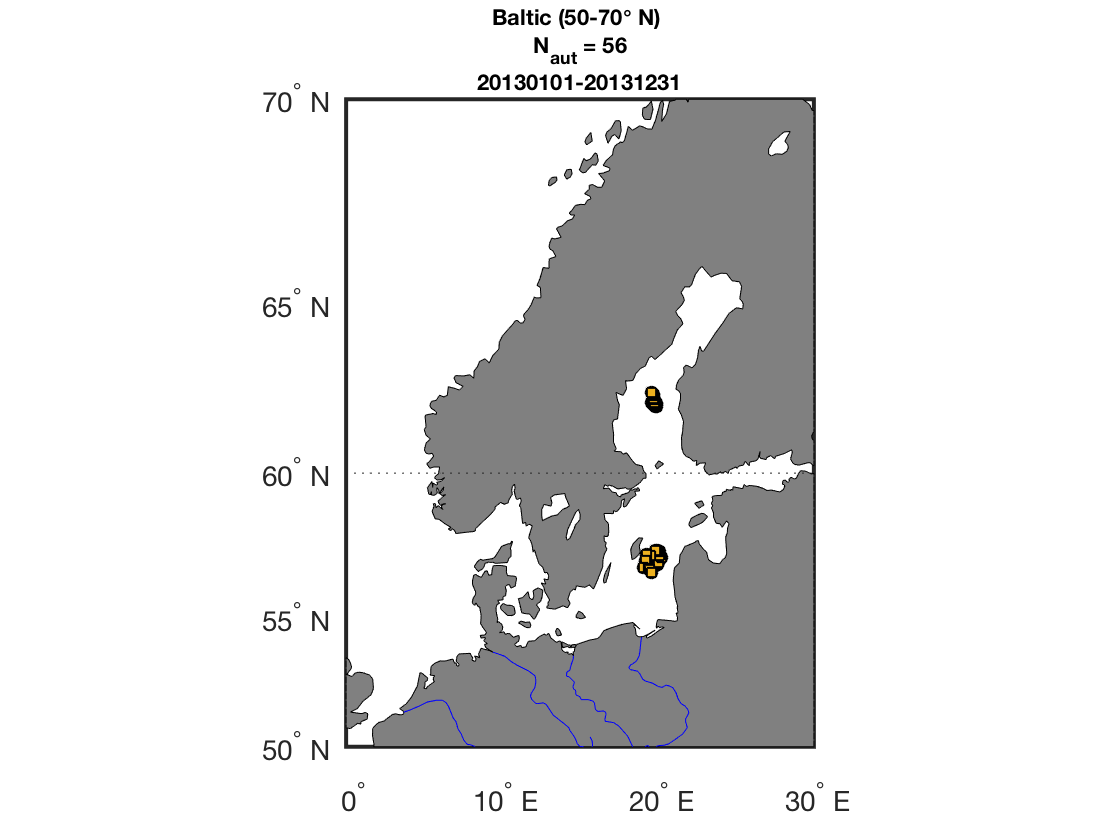

if sum(ind_ar_aut)~=0 || sum(ind_ar_aut)~=0
    
    map_projection = 'merc';
    lon_min = xmin;
    lon_max = xmax;
    lat_min = ymin;
    lat_max = ymax;
    
    lon_step = 10;
    lat_step = 5;
    
    figure; hold on
    fillmap_super(map_projection,...
        lon_min,lon_max,lat_min,lat_max,lon_step,lat_step);
    hold on
    
    title({[basin_str ' (' num2str(lat_min) '-' ...
        num2str(lat_max) '\circ N) ' ]; ...
        ['N_{aut} = ' num2str(Nobs_ar_aut)];...
        [datestr(itime_start,'yyyymmdd') '-'...
        datestr(itime_end,'yyyymmdd')]});
    hold on
    
    
    icolor = [0.9294    0.6941    0.1255]; % set FaceColor (c = uisetcolor)
    h1 = plotm(lat_aut,lon_aut,'ko','MarkerFaceColor',icolor);
    h2 = plotm(lat_aut,lon_aut,'ks','MarkerFaceColor',icolor);
    
    %     legend([h1(1),h2(1)],{['Nobs_{NA}=' num2str(Nobs_ar_NA_aut)],...
    %         ['Nobs_{PA}=' num2str(Nobs_ar_PA_aut)]},'location','southeastoutside')
    
end

## Argo Averaged profiles (T and S) in each region

dim = 2;  % average across columns (profiles)
flag = 0; % normalized std [1], or not [0]

plat_BOS = platform(ind_ar_BOS);
plat_ArB = platform(ind_ar_ArB);

T_BOS = t_intp(:,ind_ar_BOS);
T_mean_BOS = nanmean(T_BOS,dim);
T_std_BOS = nanstd(T_BOS,flag,dim);
T_SEM_BOS = T_std_BOS/(Nobs_ar_BOS).^.5; % std of the mean

T_ArB = t_intp(:,ind_ar_ArB);
T_mean_ArB = nanmean(T_ArB,dim);
T_std_ArB = nanstd(T_ArB,flag,dim);
T_SEM_ArB = T_std_ArB/(Nobs_ar_ArB).^.5; % std of the mean

S_BOS = s_intp(:,ind_ar_BOS);
S_mean_BOS = nanmean(S_BOS,dim);
S_std_BOS = nanstd(S_BOS,flag,dim);
S_SEM_BOS = T_std_BOS/(Nobs_ar_BOS).^.5; % std of the mean

S_ArB = s_intp(:,ind_ar_ArB);
S_mean_ArB = nanmean(S_ArB,dim);
S_std_ArB = nanstd(S_ArB,flag,dim);
S_SEM_ArB = T_std_ArB/(Nobs_ar_ArB).^.5; % std of the mean

P_BOS = p_intp(:,ind_ar_BOS);
P_ArB = p_intp(:,ind_ar_ArB);
P_mean = p_intp(:,1);

% Argo Seasonal classification in each region
% %
% Computation seasonal statistics, including mean, std, standard error of the
% mean (SEM).
%
% The following loop using "eval" function gives the following output (type
% AR_SEASON):
% * S_ar_aut: [501×188 double]
% * S_ar_mean_aut: [501×1 double]
% * S_ar_std_aut: [501×1 double]
% * S_ar_SEM_aut: [501×1 double]

season_str = {'wnt','spr','sum','aut'};
param = {'T','S'};
region ={'BOS','ArB'};

for yy = 1:length(season_str)
    for xx = 1: length(param)
        for zz = 1:length(region)
            
            iseason = season_str{yy};
            iparam = param{xx};
            iregion = region{zz};
            
            eval(['plat_' '_' iseason ' = platform(ind_ar_' iseason ');']);
            
            eval([iparam '_ar_' iseason ' = ' iparam  '_ar (:,ind_ar_' iseason ');']);
            eval([iparam '_ar_mean_' iseason ' = nanmean(' iparam '_ar_' iseason ',dim);']);
            eval([iparam '_ar_std_' iseason '= nanstd(' iparam '_ar_' iseason ',flag,dim);']);
            eval([iparam '_ar_SEM_' iseason ' = ' iparam '_ar_std_' iseason '/(Nobs_ar_' iseason ').^.5;']); % std of the mean
            
            AR_SEASON = struct;
            eval(['AR_SEASON.' iparam '_ar_' iseason ' = ' iparam '_ar_' iseason ';'])
            eval(['AR_SEASON.' iparam '_ar_mean_' iseason ' = ' iparam '_ar_mean_' iseason ';'])
            eval(['AR_SEASON.' iparam '_ar_std_' iseason  ' = ' iparam '_ar_std_' iseason  ';'])
            eval(['AR_SEASON.' iparam '_ar_SEM_' iseason ' = ' iparam '_ar_SEM_' iseason ';'])
        end
    end
end
% [Argo] Plot average profiles in NA and PA region

Plot TS Profiles Limits axes

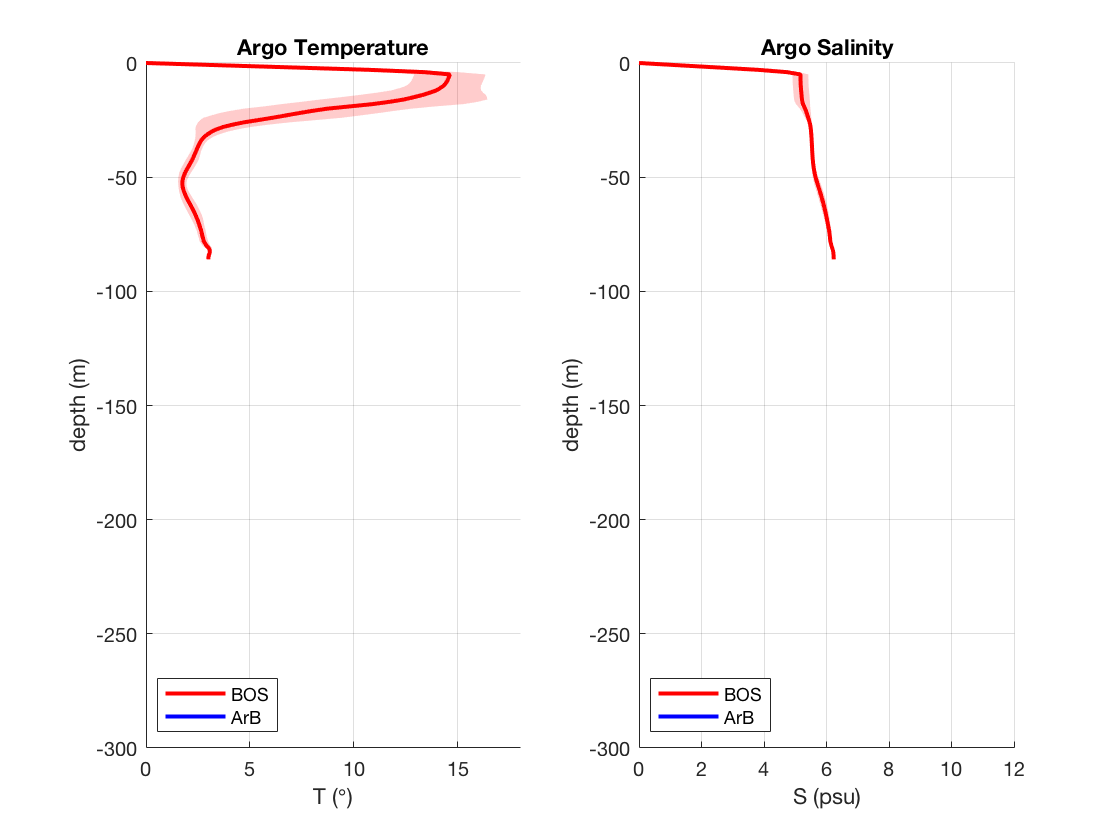

Tmin = 0;
Tmax = 18;
Smin = 0;
Smax = 12;


figure
% [1] Temperature profile
X1 = T_mean_BOS;
Y1 = -P_mean;
Z1 = T_std_BOS;

X2 = T_mean_ArB;
Y2 = -P_mean;
Z2 = T_std_ArB;

subplot(1,2,1)
h1 = boundedline(X1,Y1,Z1,...
    '-r','alpha','orientation','horiz'); hold on
h1 = plot (X1, Y1,'-','linewidth',2,'Color','r');

hold on
h2 = boundedline(X2,Y2,Z2,...
    '-b','alpha','orientation','horiz'); hold on
h2 = plot (X2, Y2,'-','linewidth',2,'Color','b');

ylim([-pres2 -pres1])
xlim ([Tmin Tmax])

xlabel ('T (\circ)'); ylabel('depth (m)')
grid on
legend ([h1(1);h2(1)],{'BOS';'ArB'},'location','SouthWest')
title('Argo Temperature');

% [2] Salinity profile

X1 = S_mean_BOS;
Y1 = -P_mean;
Z1 = S_std_BOS;

X2 = S_mean_ArB;
Y2 = -P_mean;
Z2 = S_std_ArB;

subplot(1,2,2)
h1 = boundedline(X1,Y1,Z1,...
    '-r','alpha','orientation','horiz'); hold on
h1 = plot (X1, Y1,'-','linewidth',2,'Color','r');

hold on
h2 = boundedline(X2,Y2,Z2,...
    '-b','alpha','orientation','horiz'); hold on
h2 = plot (X2, Y2,'-','linewidth',2,'Color','b');

ylim([-pres2 -pres1])
xlim ([Smin Smax])

xlabel ('S (psu)'); ylabel('depth (m)')
grid on
legend ([h1(1);h2(1)],{'BOS';'ArB'},'location','SouthWest')
title('Argo Salinity');

### [Argo] Plot average Seasonal (winter/summer) profiles in BOS region

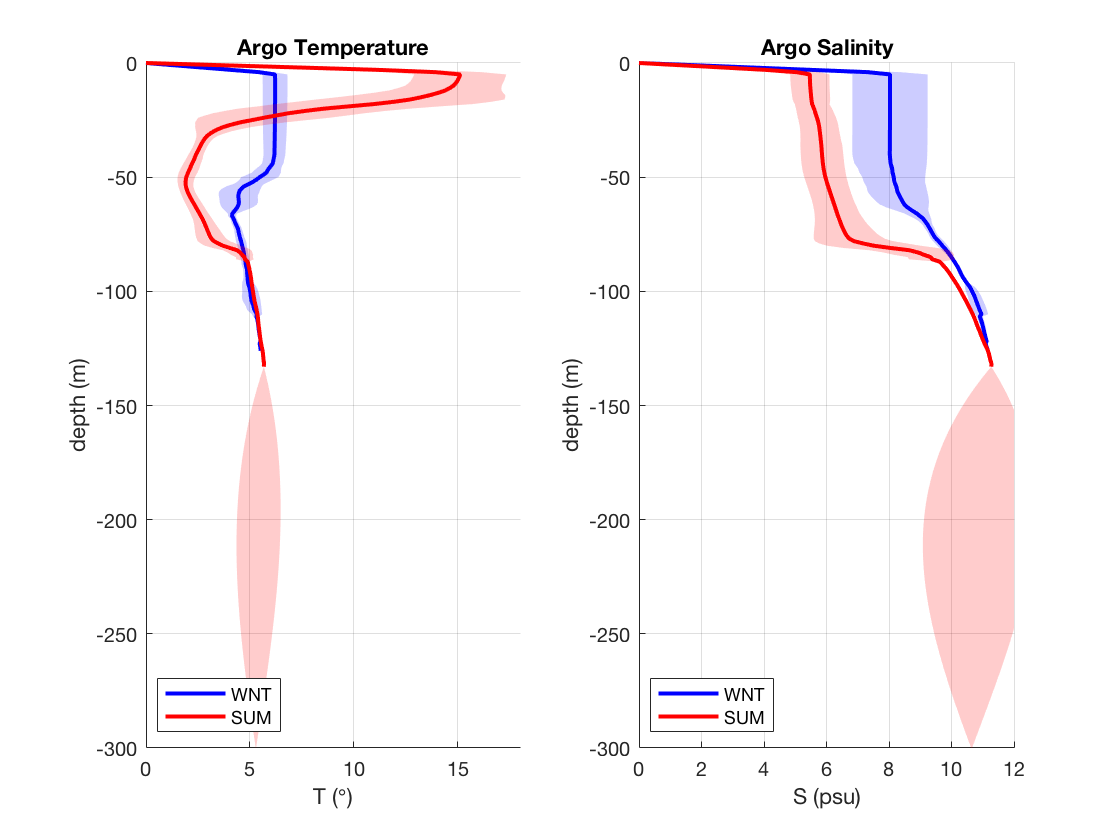

X1 = T_ar_mean_wnt;
Y1 = -P_mean;
Z1 = T_ar_std_wnt;

X2 = T_ar_mean_sum;
Y2 = -P_mean;
Z2 = T_ar_std_sum;

figure
% [1] Temperature profile
subplot(1,2,1)
h1 = boundedline(X1,Y1,Z1,...
    '-b','alpha','orientation','horiz');
hold on
h1 = plot (X1, Y1,'-','linewidth',2,'Color','b');

hold on
h2 = boundedline(X2,Y2,Z2,...
    '-r','alpha','orientation','horiz');
hold on
h2 = plot (X2, Y2,'-','linewidth',2,'Color','r');

ylim([-pres2 -pres1])
xlim ([Tmin Tmax])

xlabel ('T (\circ)'); ylabel('depth (m)')
grid on
legend ([h1(1);h2(1)],{'WNT';'SUM'},'location','SouthWest')
title('Argo Temperature');

% [2] Salinity profile

X1 = S_ar_mean_wnt;
Y1 = -P_mean;
Z1 = S_ar_std_wnt;

X2 = S_ar_mean_sum;
Y2 = -P_mean;
Z2 = S_ar_std_sum;


subplot(1,2,2)
h1 = boundedline(X1,Y1,Z1,...
    '-b','alpha','orientation','horiz');
hold on
h1 = plot (X1,Y1,'-','linewidth',2,'Color','b');
hold on
h2 = boundedline(X2,Y2,Z2,...
    '-r','alpha','orientation','horiz');
hold on
h2 = plot (X2, Y2,'-','linewidth',2,'Color','r');

ylim([-pres2 -pres1])
xlim ([Smin Smax])

xlabel ('S (psu)'); ylabel('depth (m)')
grid on
legend ([h1(1);h2(1)],{'WNT';'SUM'},'location','SouthWest')
title('Argo Salinity');

## [Mooring] Read mooring data (location: 50N 145W)

**Not done because there are not mooring stations.**

- There is no mooring data at the Baltic (at least not included in the indata)

- Alternatively plot T and S analysis profiles.

### Satellite and Argo comparison againts mooring (BOXPLOTS)

itime = itime_start; % first day of the month (i.e. use SSS colored map)

Modify script when incorporating mooring data in the Baltic

% data_type = 1;  % Arctic+
% plot_type = 3;  % lambert projection
% ibasin = 7;     % Arctic region
% region = 'PA';  % Arctic Pacific region ['PA'] or North Atlantic ['PA'])
% idepth_max = 10;% Depth (m) to compare profiles (argo and PAPA)
% 
% 
% % Get T and S at 10 m (P <= 10 m)
% 
% %[*] Argo@10m winter/summer
% [row,col] = find(P_ar_PA_irange >= idepth_max,1,'first');
% 
% T10_PA_wnt_irange = T_ar_PA_wnt_irange(row,:);
% S10_PA_wnt_irange = S_ar_PA_wnt_irange(row,:);
% P10_PA_wnt_irange = P_ar_PA_wnt_irange(row,:);
% 
% T10_PA_sum_irange = T_ar_PA_sum_irange(row,:);
% S10_PA_sum_irange = S_ar_PA_sum_irange(row,:);
% P10_PA_sum_irange = P_ar_PA_sum_irange(row,:);
% 
% %[*] PAPA@10m winter/summer
% [row,col] = find(p_mean >= 10,1,'first');
% 
% t10_papa_wnt = t_papa_wnt(row,:);
% s10_papa_wnt = s_papa_wnt(row,:);
% 
% t10_papa_sum = t_papa_sum(row,:);
% s10_papa_sum = s_papa_sum (row,:);
% 
% 
% TEMP = nan(2000,4);
% SALT = TEMP;
% 
% param_temp = {'T10_PA_wnt_irange','t10_papa_wnt','T10_PA_sum_irange','t10_papa_sum'};
% param_salt = {'S10_PA_wnt_irange','s10_papa_wnt','S10_PA_sum_irange','s10_papa_sum'};
% 
% for n = 1:4
%     
%     eval(['ind_temp = length(' param_temp{n} ');'])
%     eval(['ind_salt = length(' param_salt{n} ');'])
%     
%     eval(['TEMP(1:ind_temp,' num2str(n) ') = ' param_temp{n} ';'])
%     eval(['SALT(1:ind_salt,' num2str(n) ') = ' param_salt{n} ';'])
%     
% end
% 
% SALT(SALT<20) = NaN; % Argo showed result (1 float) with S10 below 10 psu
% 
% 
% % BOPLOT: Show Mooring Vs Argo at 10 m depth
% figure
% 
% boxplot(TEMP,param_temp)
% title({['Tepeture (Argo and moooring) at PAPA location (' num2str(idepth_max) ' km)'];num2str(iyear)});
% 
% boxplot(SALT,param_salt)
% title({['Salintiy (Argo and moooring) at PAPA location (' num2str(idepth_max) ' km)'];num2str(iyear)});
% 



### [Mooring+ARGO+SAT] Compare Salinity at 10 m depth from Mooring and ARGO Vs Satellite data

**Not done because there are not mooring stations.**

In the previous sections, plots showed that MLD is as large as 100 and 80 m in winter and summer respectively. Thus it is possible to assume that salinity at 10 m depth should compare well with the satellite retrieved salinity at skin of the of skin of the ocean (i.e. top milimeters of the surface).

Make scatterplot of salinity data including:

- Mooring salinity at 10 m (only one location)

- Argo salinity at 10 m (variable location)

- SSS map (satellite) surface map

### SSS-BEC (sss_bec) at mooring location

- Baltic+ product ranges: February 2011- December 2013

- Red SSS data at each study region (i.e. BOS, GOF,NBP and ArB).


 

itime_min = datenum(2011,02,1,0,0,0);
itime_max = datenum(2014,01,05,0,0,0);

time_range = itime_min:itime_max;

% To choose BEC product: [1] Arctic+ (v3), [2] BEC Arctic (v2), [3] Global
data_type = 4;
ibasin = 9;
if data_type == 4 % Baltic+ product (v3.0)
    data_version_str = 'Baltic_NOM_v1';
elseif data_type == 5 % Arctic BEC product (v2.0)
    data_version_str = 'Baltic_NS_v1';
elseif data_type == 3 % Use the BEC Global product (v001)
    data_version_str = 'Global_v001';
else % Use the BEC Global product (default mode)
    data_version_str = 'Global_v001';
end


[iX,iY] = find(~isnan(time_range) & time_range > itime_min & time_range <= itime_max);

lon_BOS = 19.5;
lat_BOS = 61.5;

lon_GOF = 21.5;
lat_GOF = 59.5;

lon_NBP = 19.5;
lat_NBP = 58.50;

lon_ArB = 18;
lat_ArB = 56;

regions_str ={'BOS','GOF','NBP','ArB'};
lon_regions = [lon_BOS, lon_GOF, lon_NBP,lon_ArB];
lat_regions = [lat_BOS, lat_GOF, lat_NBP, lat_ArB]; 

REGION = regions_str{1}

folder_out = [folder_tmp 'Baltic/Validation/Regions/' REGION '/SSS/'];
foldercheck_raf(folder_out)

for xx = 1:length(regions_str)
    lon_this = lon_regions(xx);
    lat_this = lat_regions(xx);
end

fn_out = [folder_out 'SSS_SMOS_BEC_L4_' data_version_str '_' REGION...
    '_r' num2str(r) '.mat'];

nTIME = length(time_range);

lon_bec = nan(nTIME,1);
lat_bec = nan(nTIME,1);
sss_bec = nan(nTIME,1);

if exist(fn_out,'file') ~= 2 % < SET TO '2' when you want to run this section! >
    for tt = 1: length(iX)
        disp ([num2str(tt) '/' num2str(length(iX))])
        ind = iX(tt);
        
        TIME2 = time_range(ind);
        
        if TIME2 >= itime_min && TIME2 <= itime_max
            
            % [TT1] = rd_smos_L4_BEC(TIME2,ibasin); % need to download data
            [TT1] = rd_smos_L4_BEC_v1r2(TIME2,ibasin,data_type);
            
            TIME_SMOS = TT1.time_out;
            SSS_SMOS = TT1.sss;
            
            LON = TT1.lon;
            LAT = TT1.lat;
            
            DIST = Distance(lon_this,lat_this,LON,LAT);
  
            
            irange = find(DIST <= r);
            
            Ln = length(irange);
            
            if Ln > 1
                lon_bec(ind,1) = nanmean(LON(irange));
                lat_bec(ind,1) = nanmean(LAT(irange));
                sss_bec(ind,1) = nanmean(SSS_SMOS(irange));
            else
                lon_bec(ind,1) = LON(irange);
                lat_bec(ind,1) = LAT(irange);
                sss_bec (ind,1) = SSS_SMOS(irange);
            end
        end
    end
    save(fn_out,'lon_bec','lat_bec','sss_bec')
elseif exist(fn_out,'file') == 2
    load(fn_out)
end

% apply a running average to data (i.e. window of 5 and 10 days averages)
wndw1 = 5;  % window1 of ndays1
wndw2 = 10; % window2 of ndays2

[sss1_bec] = movmean(sss_bec,wndw1); % sss-bec 5d averages
[sss2_bec] = movmean(sss_bec,wndw2); % sss-bec 10d averages
[sss3_bec] = movmean(sss_bec,20);    % sss-bec 20d averages

sss1_bec(1:wndw1,1) = NaN;
sss2_bec(1:wndw2,1) = NaN;

% Seasonal classification of SSS-BEC product

- This section uses the SSS-BEC data loaded in the previous section.

- Data is in format of the PAPA mooring station (i.e. the fiudecial reference)

- The seasonal classification uses the seasonal index created using time_papa (see above sections)

sss_bec_wnt = sss_bec(ind_wnt,1);
sss_bec_spr = sss_bec(ind_spr,1);
sss_bec_sum = sss_bec(ind_sum,1);
sss_bec_aut = sss_bec(ind_aut,1);

% Boxplot of the Seasonal salnity Argo, mooring and SSS-BEC values at PAPA location
param_salt = {'sss_bec_wnt', 'S10_PA_wnt_irange','s10_papa_wnt','sss_bec_sum','S10_PA_sum_irange','s10_papa_sum'};

nparam = length(param_salt);

SALT = nan(2000,nparam);

for n = 1:nparam
    
    
    eval(['ind_salt = length(' param_salt{n} ');'])
    
    
    eval(['SALT(1:ind_salt,' num2str(n) ') = ' param_salt{n} ';'])
    
end

SALT(SALT<20) = NaN; % Argo showed result (1 float) with S10 below 10 psu


% BOPLOT: Show Mooring Vs Argo at 10 m depth
figure

boxplot(SALT,param_salt)
title({['Salinity (SSS-BEC, Argo and moooring) at PAPA location (depth max=' num2str(idepth_max) ' m)'];num2str(iyear)});

nfloat_irange = length(time_ar_PA_irange);
n = 1;
itime = time_ar_PA_irange(n);

Arctic_plot_fun(ibasin,itime,data_type,plot_type,region)

% Plot PAPA location over SSS-BEC map [SCATTERPLOT]

- Mooring location with a searching radius 'r' (km)

- Background SSS-BEC product --> Show the greater spatial coverage of satellite product

figure(gcf); hold on
[c1] = plotm_study_region(lon_papa,lat_papa,r);
set(c1,'color','k','linewidth',2)
scatterm(lat_papa,lon_papa,...
    20,s_papa_intp(11,1),'filled','MarkerEdgeColor','k')